
%#ok<*CLALL>

clear all;clc 

gridSettings = gridSettingsClass; 

gridSettings.gridSize = [16, 32]; 

% Let 1 tick be 6 hours. 
gridSettings.ticksPerYear = 365*24; 

gridSettings.tickSpan = 1 : gridSettings.ticksPerYear; 

gridSettings.riskFactorMean = -1E-3; 
gridSettings.riskFactorStandardDeviation = 1E-3; 
gridSettings.riskFactorAmplitudeMean = 1E-3; 
gridSettings.riskFactorAmplitudeStandardDeviation = 1E-3/4; 

gridSettings.restoreGridHealthRate = 1/gridSettings.ticksPerYear; 

gridSettings.restoreGridHealthCost = 0; 

gridSettings.newFireIntensityMax = 1.5E-3; 
gridSettings.newFireIntensityMean = 1E-3; 
gridSettings.newFireIntensityStandardDeviation = 1E-3/4; 

gridSettings.fireIntensityScaler = 16; 
gridSettings.peakIntensityHealthMin = 0.5; 
gridSettings.peakIntensityHealthMax = 0.7; 
gridSettings.peakIntensityHealth_mean = 0.6; 
gridSettings.peakIntensityHealth_standardDeviation = 0.02; 

gridSettings.airEfficiency =2E-4 / 1.25; 
gridSettings.groundEfficiency = 5E-5; 

% Less sats sim. 
gridSettings.satelliteScanFrequency = 48; 
simGrid_0 = gridClass(gridSettings); 

% More sats sim. 
gridSettings.satelliteScanFrequency = 4; 
simGrid_1 = gridClass(gridSettings); 

% Take a peek at grid block (5, 16): 
tspan = simGrid_0.tickSpan; 
healthPeekaboo_0 = zeros(size(tspan)).'; 
scannedGridHealthPeekaboo_0 = zeros(size(tspan)).'; 
healthPeekaboo_1 = zeros(size(tspan)).'; 
scannedGridHealthPeekaboo_1 = zeros(size(tspan)).'; 

tic;
for tick = tspan
    % Simulation grid 0. 
    simGrid_0.updateGrid(); 
    healthPeekaboo_0(tick) = simGrid_0.gridHealth(5, 16); 
    scannedGridHealthPeekaboo_0(tick) = simGrid_0.fireScan.scannedGridHealth(5, 16); 

    % Simulation grid 1. 
    simGrid_1.updateGrid(); 
    healthPeekaboo_1(tick) = simGrid_1.gridHealth(5, 16); 
    scannedGridHealthPeekaboo_1(tick) = simGrid_1.fireScan.scannedGridHealth(5, 16); 
end

Ground Unit Mobilized 400.9304
Ground Unit Mobilized 408.6003
Ground Unit Mobilized 407.4176
Ground Unit Mobilized 411.5622
Ground Unit Mobilized 406.9373
Ground Unit Mobilized 406.6627
Ground Unit Mobilized 402.5441
Ground Unit Mobilized 436.3253


Ground Unit Mobilized 410.6555


Ground Unit Mobilized 400.4818


Ground Unit Mobilized 431.3929
Ground Unit Mobilized 415.7961
Ground Unit Mobilized 407.5347
Ground Unit Mobilized 405.8888


Ground Unit Mobilized 444.4001


Ground Unit Mobilized 401.4315
Ground Unit Mobilized 403.1813
Ground Unit Mobilized 409.5502
Ground Unit Mobilized 409.5574
Ground Unit Mobilized 409.5649
Ground Unit Mobilized 406.4344
Air Unit Mobilized1018.2112
Ground Unit Mobilized 424.4934
Ground Unit Mobilized 419.9022
Ground Unit Mobilized 407.7694
Air Unit Mobilized1003.1126
Air Unit Mobilized1006.99
Ground Unit Mobilized 403.3513
Air Unit Mobilized1022.169
Ground Unit Mobilized 406.0675
Ground Unit Mobilized 428.1233


Ground Unit Mobilized 411.0647
Air Unit Mobilized1116.1696
Ground Unit Mobilized 440.8704
Air Unit Mobilized1062.9894
Ground Unit Mobilized 415.0963


Ground Unit Mobilized 410.501


Ground Unit Mobilized 405.377
Ground Unit Mobilized 425.8411
Ground Unit Mobilized 407.7894
Ground Unit Mobilized 417.1854
Ground Unit Mobilized 404.8054
Ground Unit Mobilized 413.6248
Ground Unit Mobilized 405.5372
Ground Unit Mobilized 402.6915
Ground Unit Mobilized 408.2983


Ground Unit Mobilized 418.9576


Ground Unit Mobilized 410.653
Ground Unit Mobilized 406.5916
Ground Unit Mobilized 418.2223
Ground Unit Mobilized 418.58
Ground Unit Mobilized 418.3849
Ground Unit Mobilized 430.9239
Ground Unit Mobilized 401.0358
Ground Unit Mobilized 400.6846
Ground Unit Mobilized 408.4133


Ground Unit Mobilized 403.1859
Ground Unit Mobilized 407.9085
Ground Unit Mobilized 402.3499
Ground Unit Mobilized 401.8962
Ground Unit Mobilized 434.8876
Ground Unit Mobilized 423.5179
Ground Unit Mobilized 425.1455
Ground Unit Mobilized 442.8053
Ground Unit Mobilized 442.321
Ground Unit Mobilized 442.2198
Ground Unit Mobilized 442.3415
Ground Unit Mobilized 403.3161
Ground Unit Mobilized 464.5151
Air Unit Mobilized1039.6079
Air Unit Mobilized1036.6391
Air Unit Mobilized1020.0986
Ground Unit Mobilized 417.1018
Ground Unit Mobilized 413.5387
Air Unit Mobilized1017.5924
Ground Unit Mobilized 446.2104
Ground Unit Mobilized 401.0052
Ground Unit Mobilized 426.8544
Air Unit Mobilized1016.5184
Ground Unit Mobilized 407.2872
Air Unit Mobilized1008.7779


Air Unit Mobilized1020.7199
Ground Unit Mobilized 468.3421
Ground Unit Mobilized 416.3202
Ground Unit Mobilized 410.1838
Ground Unit Mobilized 402.7779


Ground Unit Mobilized 411.549


toc;

Elapsed time is 55.501755 seconds.


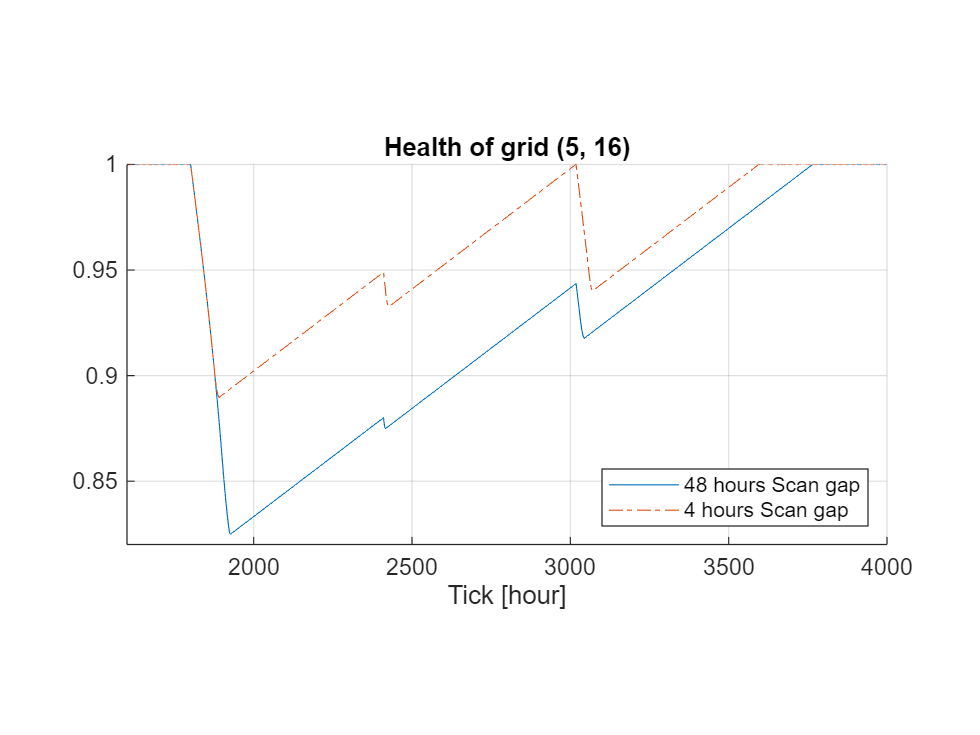

% clf; 
% subplot(1, 2, 1); 
% hold on; 
% grid on; 
% plot(tspan, healthPeekaboo_0, ":"); 
% plot(tspan, healthPeekaboo_1, ":"); 
% xlabel("Tick [hour]"); 
% title("Health of grid (5, 16)"); 
% legend( ...
%     "Less Sats, true health", ...
%     "More Sats, true health", ...
%     "Location", "southeast"); 
% axis([1750 3800 0.865 1]); 
% pbaspect([2 1 1]); 
% hold off; 
% subplot(1, 2, 2); 
% hold on; 
% grid on; 
% plot(tspan, scannedGridHealthPeekaboo_0); 
% plot(tspan, scannedGridHealthPeekaboo_1); 
% xlabel("Tick [hour]"); 
% title("Satellite scanned health of grid (5, 16)"); 
% legend( ...
%     "Less Sats, scanned health", ...
%     "More Sats, scanned health", ...
%     "Location", "southeast"); 
% axis([1750 3800 0.865 1]); 
% pbaspect([2 1 1]); 
% hold off; 
clf; 
hold on; 
grid on; 
plot(tspan, healthPeekaboo_0); 
plot(tspan, healthPeekaboo_1, "-."); 
xlabel("Tick [hour]"); 
title("Health of grid (5, 16)"); 
legend( ...
    "48 hours Scan gap", ...
    "4 hours Scan gap", ...
    "Location", "southeast"); 
axis([1600 4000 0.82 1]); 
pbaspect([2 1 1]); 
hold off; 

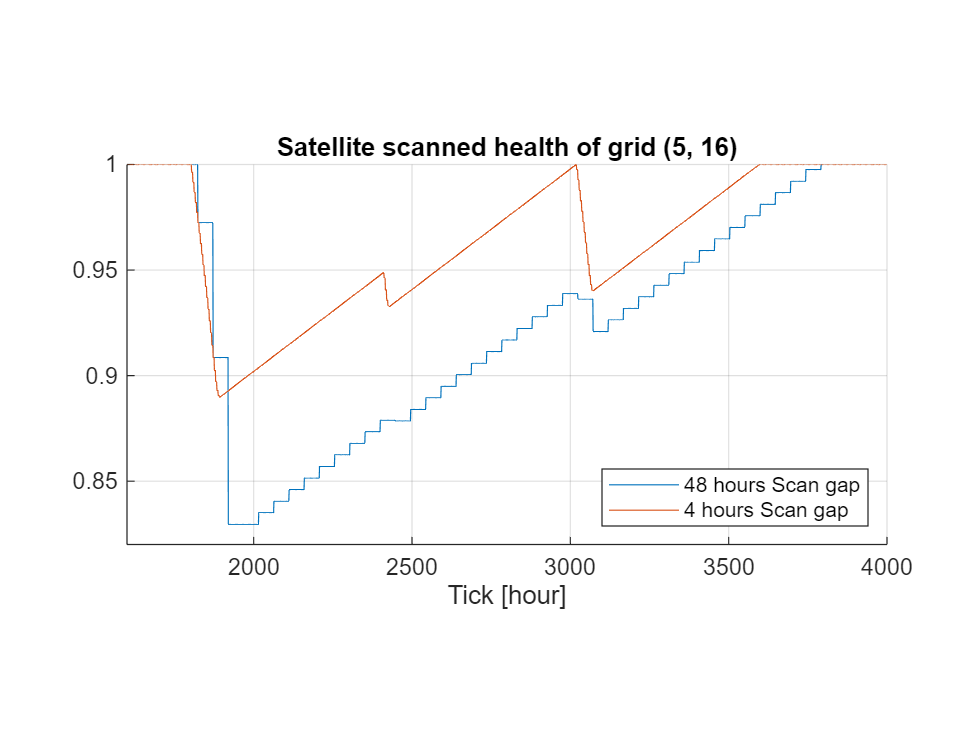

clf; 
hold on; 
grid on; 
plot(tspan, scannedGridHealthPeekaboo_0); 
plot(tspan, scannedGridHealthPeekaboo_1); 
xlabel("Tick [hour]"); 
title("Satellite scanned health of grid (5, 16)"); 
legend( ...
    "48 hours Scan gap", ...
    "4 hours Scan gap", ...
    "Location", "southeast"); 
axis([1600 4000 0.82 1]); 
pbaspect([2 1 1]); 
hold off; 